## Multiplikative Modultion (Cosinus): Q-PSK Signal, Realteilbildung im Bandpass

% Alles löschen und aufräumen
close all; clear all; clc;
% Zusätzlich Pfad vom ersten Übungsblatt angeben -> Für plotfft
addpath('../../../60_Labor/01_Uebungsblatt_Musterloesung/');   
addpath('../../../60_Labor/02_Uebungsblatt_Musterloesung/');   

### Anlegen der Signale

% Festlegung der Parameter
fa = 500e6; Ta = 1 / fa;
fs = 1000; Ts = 1 / fs;
fc = 8e3;
fc2 = 100e6;

% Festlegung der Frequenz für die Symbole
f0 = 2000;
f1 = -f0;

% Erstellen von zufälligen Bits
Nbits = 50;
bits = round(rand(1, Nbits), 0);

% Berechnung der Signallänge für reeller harmonische Schwingung
Nsym = Nbits;
N_samples = floor(Nsym * (Ts / Ta)); 
Tf = Ta * N_samples - Ta;

% Erzeugung der Signale
yfpsk = FskGen(bits, fs, fa, f0, f1, 'comp');
yexp_mod = SigGen(Tf, fa, 'expj', fc);
yexp_mod2 = SigGen(Tf, fa, 'cos', fc2);

### Darstellung des Basisband-Signals

disp('F-PSK Signal im Basisband');

F-PSK Signal im Basisband


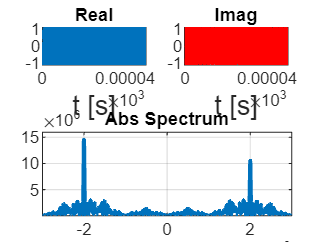

plotfft(yfpsk, fa, 'DisplaySignal', 'both', 's', 1, 'Title', "F-PSK-Signal im Basisband");
xlim([-3000, 3000]);

### Modulation des Signals

% Multiplikation der Signale
yfpsk_bp = yfpsk .* yexp_mod;

### Darstellung des Bandpass-Signals

disp('F-PSK Signal im Bandpass');

F-PSK Signal im Bandpass


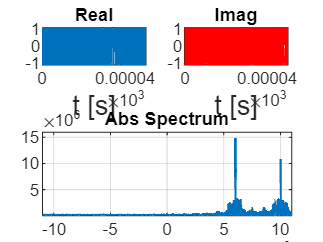

plotfft(yfpsk_bp, fa, 'DisplaySignal', 'both', 's', 1, 'Title', "F-PSK-Signal im Bandpass");
xlim([-11000, 11000]);

disp('Es sind bei -8000Hz keine Spiegelfrequenzen vorhanden');

Es sind bei -8000Hz keine Spiegelfrequenzen vorhanden


### Realteilbildung im Bandpass

Hier kann der Realteil gebildet werden ohne das Information verloren geht! 

% Realteilbildung
yfpsk_bp_real = real(yfpsk_bp)

yfpsk_bp_real =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000



disp('F-PSK Signal im Bandpass nach Realteilbildung');

F-PSK Signal im Bandpass nach Realteilbildung


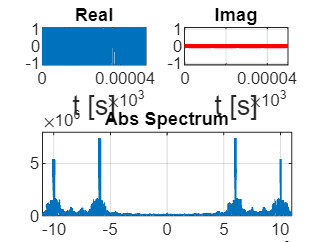

plotfft(yfpsk_bp_real, fa, 'DisplaySignal', 'both', 's', 1, 'Title', "F-PSK-Signal im Bandpass nach Realteilbildung");
xlim([-11000, 11000]);

disp('Nach der Realteilbildung tauchen die Spiegelfrequenzen bei -8000Hz auf');

Nach der Realteilbildung tauchen die Spiegelfrequenzen bei -8000Hz auf


**Allerdings: **Durch die Realteilbildung entstehen Spiegelfrequenzen. Dies entstehen zwangsläufig durch die Bildung des Realen Signals. Problematisch könnte dies werden, wenn das Signal nach D/A Wandlung noch auf einen reellen Mischer gegeben wird, um so von einem Zwischenband (8kHz) in eine höhere Frequenz gemischt wird, zum Beispiel: 100Mhz:

% Multiplikation der Signale
yfpsk_bp2 = yfpsk_bp_real .* yexp_mod2;
disp('F-PSK Signal im (Ziel-)Bandpass nach Realteilbildung und (reellen) Mischer');

F-PSK Signal im (Ziel-)Bandpass nach Realteilbildung und (reellen) Mischer


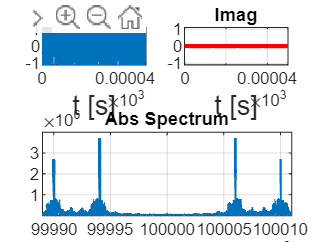

plotfft(yfpsk_bp2, fa, 'DisplaySignal', 'both', 's', 1, 'Title', "F-PSK-Signal im Bandpass nach Realteilbildung");
xlim([100e6 - 11000, 100e6 + 11000]);

disp('Durch das erneute Mischen, tauchen nun auch die Spiegelfrequenzen im Zielband auf');

Durch das erneute Mischen, tauchen nun auch die Spiegelfrequenzen im Zielband auf
